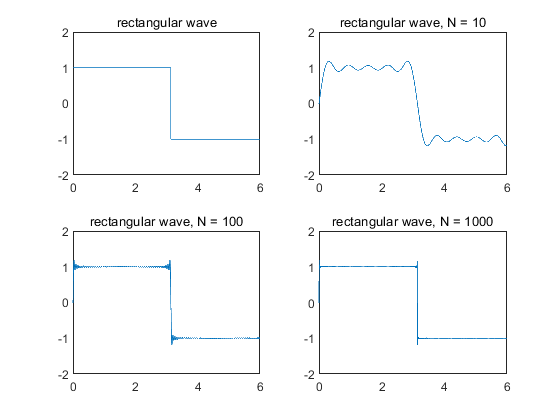

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 구형파에 대한 푸리에 급수를 구하라

clear; clc;

T = 2*pi;
freq = 1/T;
step_time = 0.001;
t = 0:step_time:T;

% origin fuction
syms y(x)
y(x) = piecewise((0 < x) & (x < pi), 1,(pi < x) & (x < 2*pi), -1);
subplot(2, 2, 1);
fplot(y(x));
title('rectangular wave');
axis([0, 6, -2, 2]);

N = 10;
f_t3 = zeros(size(t));
for n=1:N
    if(rem(n,2) == 1)
        bn = 4/(n*pi);
        f_t3 = f_t3 + bn*sin(n*t);
        subplot(2, 2, 2);
        plot(t, f_t3);
        title('rectangular wave, N = 10');
        axis([0, 6, -2, 2]);
        pause(0.0001);
    end
end

N = 100;
f_t2 = zeros(size(t));
for n=1:N
    if(rem(n,2) == 1)
        bn = 4/(n*pi);
        f_t2 = f_t2 + bn*sin(n*t);
        subplot(2, 2, 3);
        plot(t, f_t2);
        title('rectangular wave, N = 100');
        axis([0, 6, -2, 2]);
        pause(0.0001);
    end
end

f_t3 = zeros(size(t));
N = 1000;
for n=1:N
    if(rem(n,2) == 1)
        bn = 4/(n*pi);
        f_t3 = f_t3 + bn*sin(n*t);
        subplot(2, 2, 4);
        plot(t, f_t3);
        title('rectangular wave, N = 1000');
        axis([0, 6, -2, 2]);
        pause(0.0001);
    end
end